## MULTI-HH TRAIN EXPERIMENT

**CLEANING AND FOLDERS**

%First let's clean everything and add needed folders
clc
clear
close all

addpath(genpath('extended/Domains/JSSP')); % Adds JSSP functionality
addpath(genpath('extended/Utils')); % Adds assorted utilities

**LOADING FILES**

%Loading sets of instances
load('instances_adv1.mat')
load('instances_adv2.mat')
load('instances_adv1_adv2_comb.mat')

load('FM_CHH1.mat')

**TRAINING**

FM_CHH1.trainingInstances={instances_comb{[1 100]}};

properties = struct('verboseMode', true, ...
                        'maxIter', 10, 'maxStagIter', 10);
FM_CHH1.train('UPSO', properties)


[  09:24:19] UPSO2 starts...
         ... Inputs and outputs checked!
         ... Parameters initialised:

           visualMode: 0
          verboseMode: 1
       populationSize: 15
              maxIter: 10
          maxStagIter: 10
             selfConf: 2
           globalConf: 2.5000
          unifyFactor: 0.2500
      numberVariables: 6
    simpleConstraints: 1
             knownMin: -Inf
              stagTol: 0.1000
              funcTol: 1.0000e-03
               solTol: 1.0000e-06
         fitnessLimit: 1.0000e-06
          kappaFactor: 1
            phiFactor: 4.5000
       initialVelMode: 'rand'

         ... Neighbours established
         ... Population positions randomly initialised
         ... Population velocities randomly initialised
         ... Population initialised
         ... Search space adjusted
         ... Particular best fitness values determined

[Step     1] Global best fitness updated: 62.19
         ... Initialisation completed!

[Step     2] Global 

ans =     0.0269
    0.4776
    0.1741
    0.6258
    1.9593
    1.1185


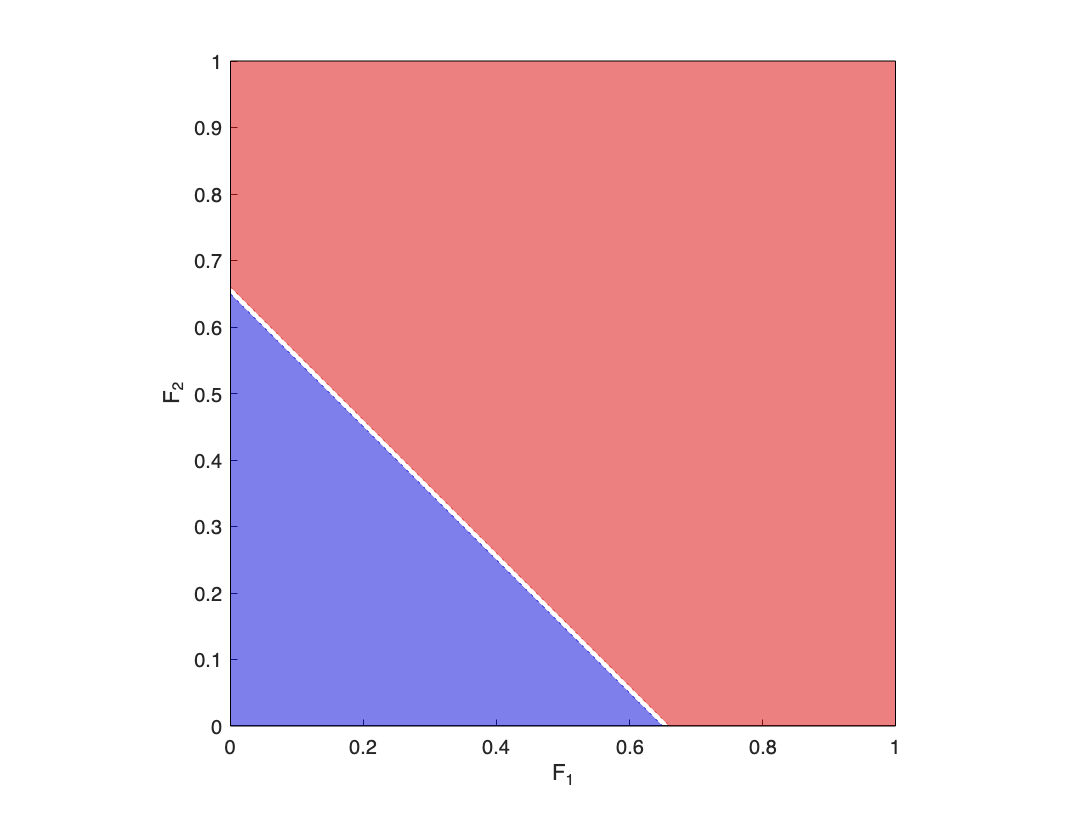

ans =     0.7822    0.2112


FM_CHH1.plotZones